# Grafica de lo la funcion norma

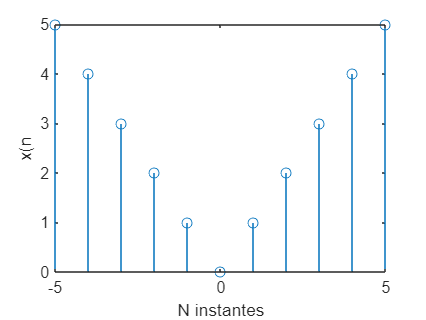

a=5; n=-a:a;
f=abs(n);%varible dependiente
stem(n,f); xlabel("N instantes");ylabel("x(n")

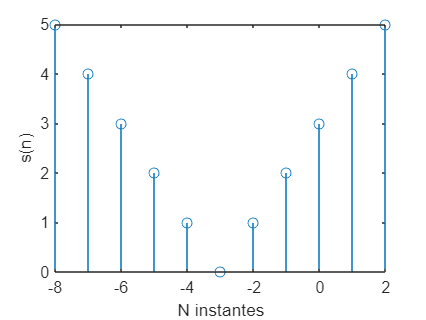


%Desplazamiento de adelanto 
d=3;
n2=n-3;
figure("Name","Señal adelantada 3 n")
stem(n2,f); xlabel("N instantes");ylabel("s(n)")


%p0 es la poscions del cero
%nsup es la poscion del n superior
%nsup=long-p0
%ninf =-(long -nsup-1)
%ninf =-(long -long+p0-1)
%ninf=(1-p0)
p0=9;
nsup=length(n)-p0

nsup = 2

ninf=1-p0

ninf = -8

# Combinación Lineal 

#### 20/09/2022

Una combinacíon lineal es un suma pesada de varias entradas


$$\[
\sum_{i=1}^{3}Peso_{i}*NotaCorte_{i}=NotaSemestre
\]$$


Calcular la combiancion lineal de la nota minima del tercer corte para no perder 


$$\[
Notacorte_{k}=\frac{3.0-\sum_{i=1}^{k-1}Peso_{i}*NotaCorte_{i}}{peso_{k}}
\]$$


Combianción lineal de una señal discreta


$$\[
S(n)=\sum_{K=1}^{N-1}C_{K}*Cos_{K}(2\pi\frac{1}{N}kn)}
\]
$$



$$\[
X_{K=1}(n) --> Fundamental \\
X_{K=0}(n) --> Componente DC
\]$$


function s=micombinacion(n,numCiclos,N)
    num_n=numCiclos*N;
    n=0:num_n-1;
    s=ones(length(n));
    for(k=1:N-1)
        s=s+cos(2*pi*(1/N)*k*n)
    end

end